# **Integrate and Classify Normals **· Getting Started

Suite of tools to integrate multinormals in any domain, compute pdf's and cdf's of any function of a multinormal variable, and compute quantities concerning classification performance among two or more multinormals.

Type `help integrate_normal`, `help classify_normals`, or `help classify_normals_multi` for more documentation.

## Integrate in 1d

### In a quadratic domain `x^2-x-1<0`, i.e. `q(x)= -1*x^2 + 1*x + 1 >0`

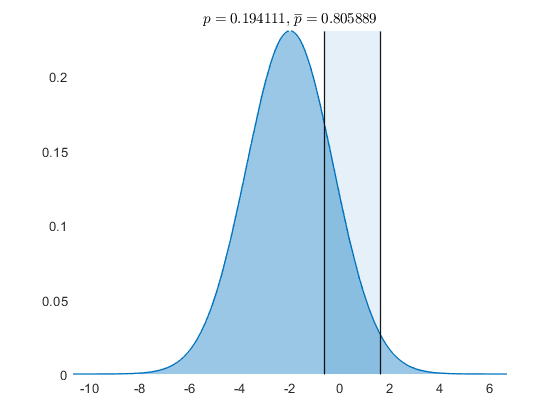

mu=-2; v=3;

dom_quad.q2=-1;
dom_quad.q1=1;
dom_quad.q0=1;

integrate_normal(mu,v,dom_quad);

Most plots can be zoomed and panned.

### Integrate in a domain defined by a non-quadratic `f(x)>0`

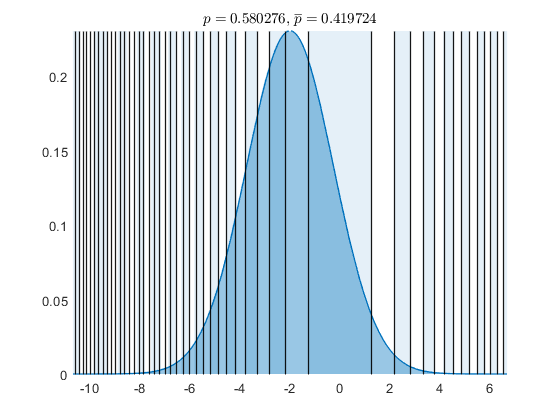

fun=@(x) cos(x.^2);
figure;
integrate_normal(mu,v,fun,'dom_type','fun','fun_span',5,'fun_resol',500);

### Plot the pdf and cdf of `f(x)`

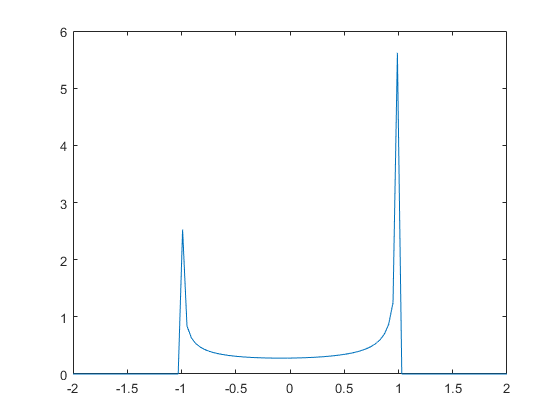

x=linspace(-2,2,100);
f=norm_fun_pdf(x,mu,v,fun,'fun_span',5,'fun_resol',500,'dx',1e-2);
figure; plot(x,f);

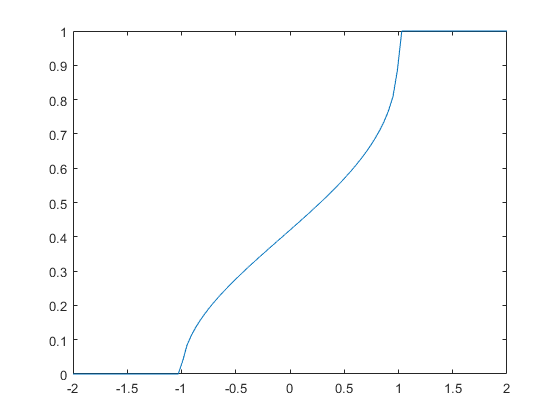

F=norm_fun_cdf(x,mu,v,fun,'fun_span',5,'fun_resol',500);
figure; plot(x,F);

## Classify in 1d

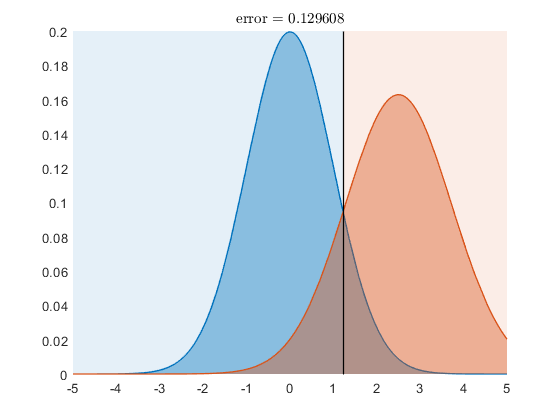

results = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [-11.2223 1.2223]
         norm_errmat: [2×2 double]
            norm_err: 0.1296
         norm_dprime: 2.2565
    norm_maha_dprime: 2.2361


mu_1=0; v_1=1;
mu_2=2.5; v_2=1.5;

results=classify_normals([mu_1,v_1],[mu_2,v_2])

### With unequal priors and outcome values

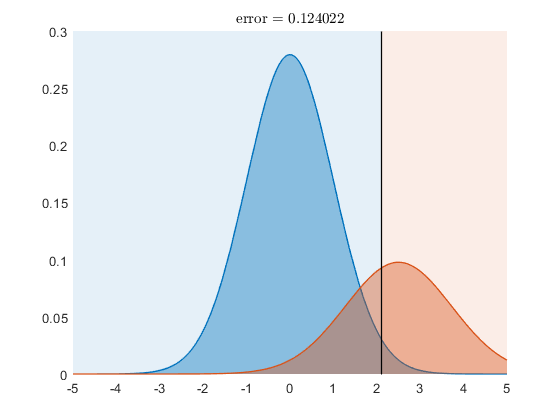

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_bd_pts: [-12.0987 2.0987]
    norm_errmat: [2×2 double]
       norm_err: 0.1240
    norm_valmat: [2×2 double]
       norm_val: 2.2509


results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[3 0; 0 1])

## Classify in 1d using samples

Priors are assumed prop. to sample sizes.

 
 Iteration   Func-count     min f(x)         Procedure
     0            1             -812         
     1            4             -812         initial simplex
     2            5             -812         reflect
     3           10             -812         shrink
     4           11             -812         reflect
     5           16             -812         shrink
     6           18             -812         contract inside
     7           23             -812         shrink
     8           28             -812         shrink
     9           30             -812         contract outside
    10           32             -812         contract inside
    11           37             -812         shrink
    12           42             -812         shrink
    13           44             -812         contract inside
    14           49             -812         shrink
    15           54             -812         shrink
    16           59             -812         shrink
    17           

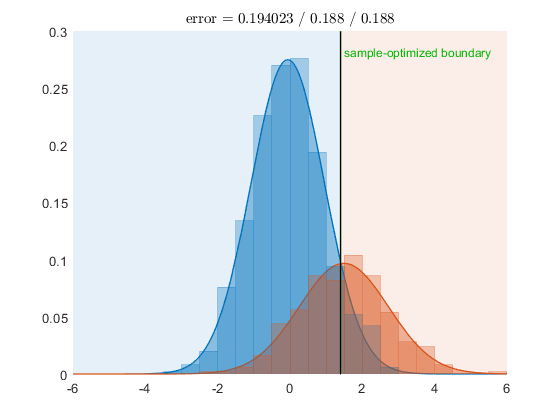

results = struct with fields:
            norm_bd: [1×1 struct]
        norm_bd_pts: [-7.9635 1.4081]
        norm_errmat: [2×2 double]
           norm_err: 0.1940
        samp_errmat: [2×2 double]
           samp_err: 0.1880
            samp_dv: {[700×1 double]  [300×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[700×1 double]  [300×1 double]}
    samp_opt_bd_pts: [-7.9635 1.4081]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.1880


mu_1=0; v_1=1;
samp_1=normrnd(mu_1,sqrt(v_1),[700 1]);

mu_2=1.5; v_2=1.5;
samp_2=normrnd(mu_2,sqrt(v_2),[300 1]);

results=classify_normals(samp_1,samp_2,'input_type','samp')

## Integrate in 2d

in a quadratic domain $(x+y)^2 > x+1$, i.e. `q(x,y)= [x y]*[1 1; 1 1]*[x;y] + [-1 0]*[x;y] -1 > 0`

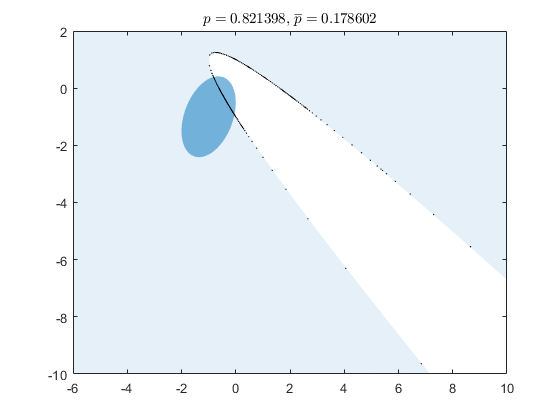

mu=[-1; -1]; v=[1 0.5; 0.5 2];

dom_quad.q2=[1 1; 1 1];
dom_quad.q1=[-1;0];
dom_quad.q0=-1;

% compare two integration algorithms
figure; integrate_normal(mu,v,dom_quad); % ray method
xlim([-6 10]); ylim([-10 2])

figure; integrate_normal(mu,v,dom_quad,'method','gx2'); % gx2 method

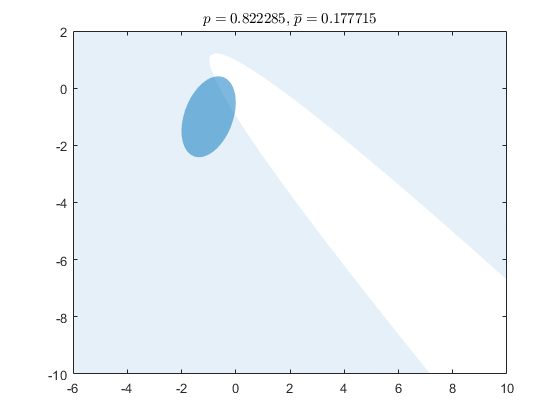

xlim([-6 10]); ylim([-10 2])

## Classify two 2d normals, one inside the other

mu_1=[4; 5]; v_1=[2 1; 1 1];
mu_2=mu_1; v_2=3*[2 -1; -1 1];

% compare two integration algorithms
results_ray=classify_normals([mu_1,v_1],[mu_2,v_2]) % ray method

results_ray = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [2×414 double]
         norm_errmat: [2×2 double]
            norm_err: 0.1979
         norm_dprime: 1.6982
    norm_maha_dprime: 0


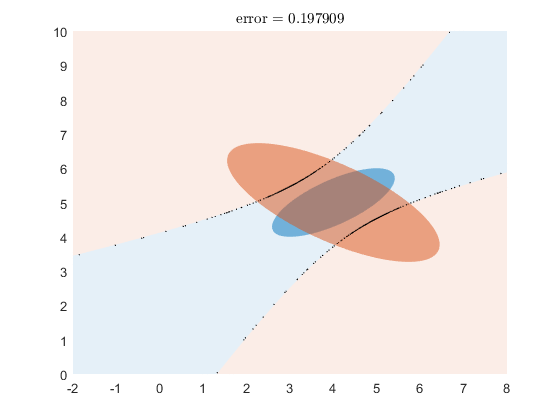

xlim([-2 8]); ylim([-0 10]);

results_gx2=classify_normals([mu_1,v_1],[mu_2,v_2],'method','gx2') % gx2 method

results_gx2 = struct with fields:
             norm_bd: [1×1 struct]
         norm_errmat: [2×2 double]
            norm_err: 0.1979
         norm_dprime: 1.6982
    norm_maha_dprime: 0


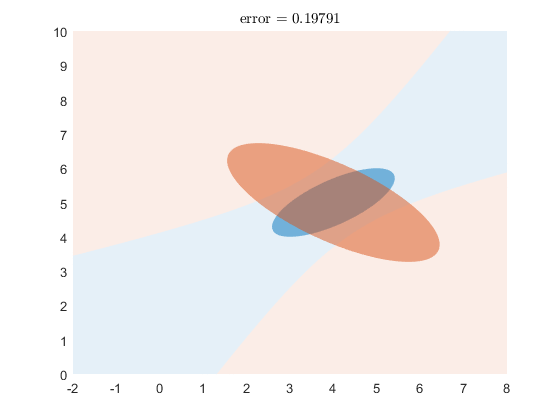

xlim([-2 8]); ylim([-0 10]);

## PAPER Classify in 2d with custom boundaries and from samples

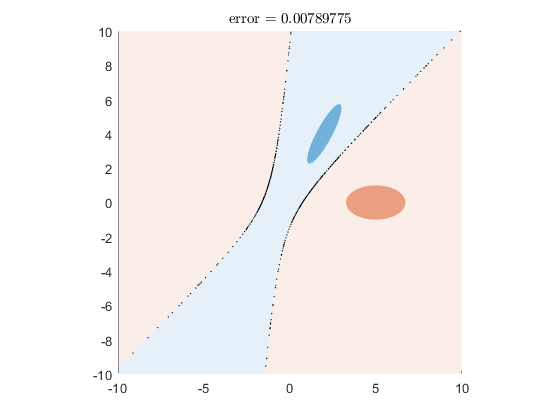

mu_1=[2;4]; v_1=[1 1.5; 1.5 3];
mu_2=[5;0]; v_2=[3 0; 0 1];

% ray method
results_ray=classify_normals([mu_1,v_1],[mu_2,v_2]); 
axis image; xlim([-10 10]); ylim([-10 10])

results_ray.norm_err

ans = 0.0079

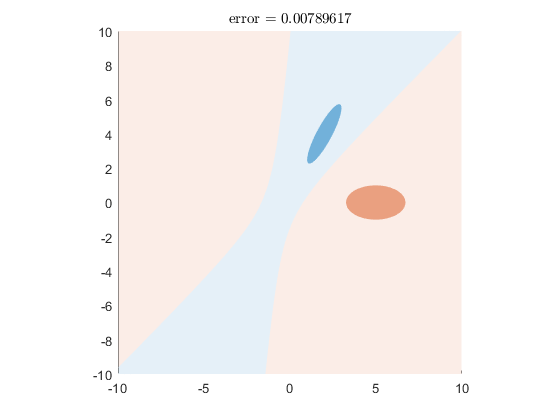


% compare with generalized chi square method
results_gx2=classify_normals([mu_1,v_1],[mu_2,v_2],'method','gx2'); 
axis image; xlim([-10 10]); ylim([-10 10])

results_gx2.norm_err

ans = 0.0079


% now supply a custom linear boundary
linear_bd.q2=zeros(2);
linear_bd.q1=[-.7;1];
linear_bd.q0=0;

results_linear=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',linear_bd)

results_linear = struct with fields:
    norm_bd_pts: [2×300 double]
    norm_errmat: [2×2 double]
       norm_err: 0.0133


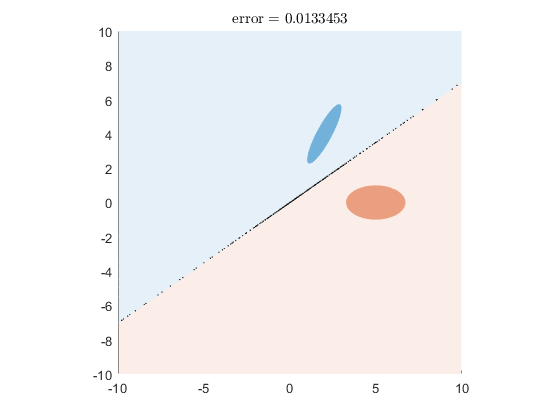

axis image; xlim([-10 10]); ylim([-10 10])


% now classify using samples
n_samp=1e3;
samp_1=mvnrnd(mu_1,v_1,n_samp);
samp_2=mvnrnd(mu_2,v_2,n_samp);

results_samp=classify_normals(samp_1,samp_2,'input_type','samp')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1983         
     1            7            -1984         initial simplex
     2            8            -1984         reflect
     3           10            -1984         contract outside
     4           11            -1984         reflect
     5           12            -1984         reflect
     6           20            -1984         shrink
     7           22            -1984         contract outside
     8           30            -1984         shrink
     9           38            -1984         shrink
    10           46            -1984         shrink
    11           54            -1984         shrink
    12           62            -1984         shrink
    13           70            -1984         shrink
    14           78            -1984         shrink
    15           86            -1984         shrink
    16           94            -1984         shrink
    17          102            -1

results_samp = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [2×520 double]
         norm_errmat: [2×2 double]
            norm_err: 0.0091
         norm_dprime: 4.7271
    norm_maha_dprime: 4.3698
         samp_errmat: [2×2 double]
            samp_err: 0.0085
         samp_dprime: 4.7734
             samp_dv: {[1000×1 double]  [1000×1 double]}
         samp_opt_bd: [1×1 struct]
         samp_opt_dv: {[1000×1 double]  [1000×1 double]}
     samp_opt_bd_pts: [2×32518 double]
     samp_opt_errmat: [2×2 double]
        samp_opt_err: 0.0080
     samp_opt_dprime: 4.8178


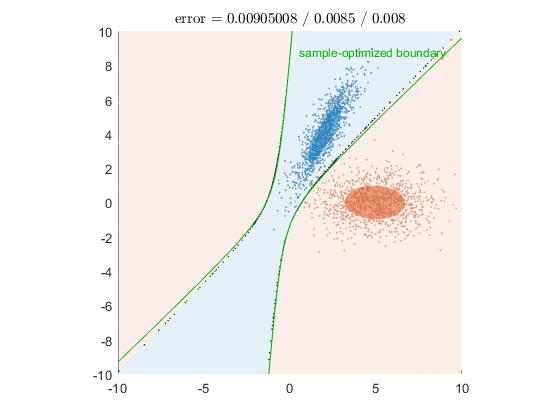

axis image; xlim([-10 10]); ylim([-10 10])


% modify the sample-optimized boundary and classify with it
custom_bd=results_samp.samp_opt_bd;
custom_bd.q2=custom_bd.q2+.1;
custom_bd.q1=custom_bd.q1-2.5;
custom_bd.q0=custom_bd.q0+5;

results_samp_custom=classify_normals(samp_1,samp_2,'input_type','samp','dom',custom_bd)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1968         
     1            7            -1974         initial simplex
     2            9            -1976         expand
     3           10            -1976         reflect
     4           11            -1976         reflect
     5           12            -1976         reflect
     6           14            -1979         expand
     7           15            -1979         reflect
     8           16            -1979         reflect
     9           17            -1979         reflect
    10           19            -1980         reflect
    11           20            -1980         reflect
    12           21            -1980         reflect
    13           22            -1980         reflect
    14           24            -1980         contract inside
    15           32            -1980         shrink
    16           40            -1980         shrink
    17           48            -1980 

results_samp_custom = struct with fields:
        norm_bd_pts: [2×420 double]
        norm_errmat: [2×2 double]
           norm_err: 0.0195
        samp_errmat: [2×2 double]
           samp_err: 0.0160
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_bd_pts: [2×26852 double]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.0100


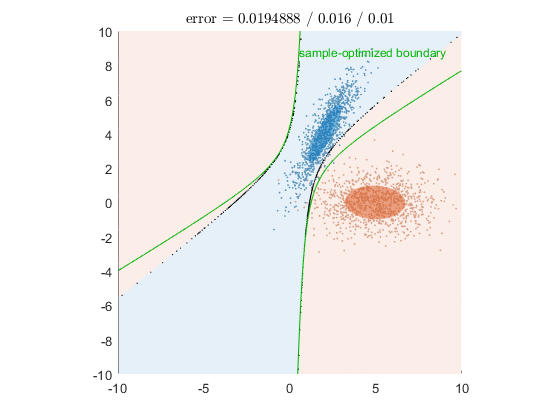

axis image; xlim([-10 10]); ylim([-10 10])

## Classify in 2d with non-normal samples

n_samp=1e3;
samp_1=exp(mvnrnd([0 0],eye(2),n_samp));
samp_2=-exp(mvnrnd([1 1],eye(2),n_samp))+[2 2];

results=classify_normals(samp_1,samp_2,'input_type','samp')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1516         
     1            7            -1522         initial simplex
     2            9            -1539         expand
     3           10            -1539         reflect
     4           11            -1539         reflect
     5           12            -1539         reflect
     6           14            -1554         expand
     7           15            -1554         reflect
     8           17            -1578         expand
     9           18            -1578         reflect
    10           19            -1578         reflect
    11           21            -1606         expand
    12           22            -1606         reflect
    13           23            -1606         reflect
    14           25            -1647         expand
    15           26            -1647         reflect
    16           28            -1670         expand
    17           30            -1740         ex

results = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [2×488 double]
         norm_errmat: [2×2 double]
            norm_err: 0.1307
         norm_dprime: 2.2464
    norm_maha_dprime: 1.4654
         samp_errmat: [2×2 double]
            samp_err: 0.2420
         samp_dprime: 1.3998
             samp_dv: {[1000×1 double]  [1000×1 double]}
         samp_opt_bd: [1×1 struct]
         samp_opt_dv: {[1000×1 double]  [1000×1 double]}
     samp_opt_bd_pts: [2×29380 double]
     samp_opt_errmat: [2×2 double]
        samp_opt_err: 0.1085
     samp_opt_dprime: 2.4691


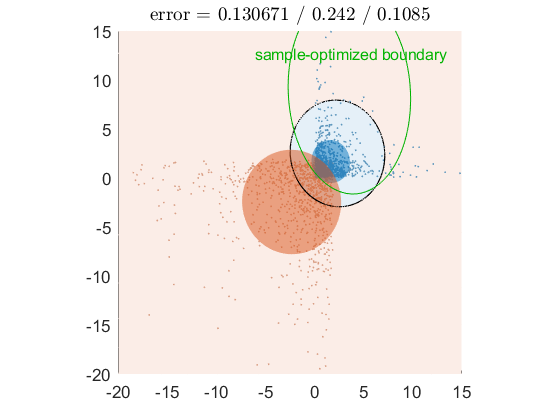

axis image; xlim([-20 15]); ylim([-20 15])
set(gca,'fontsize',13); box off

## Inversion/union/intersection of integration/classification domains

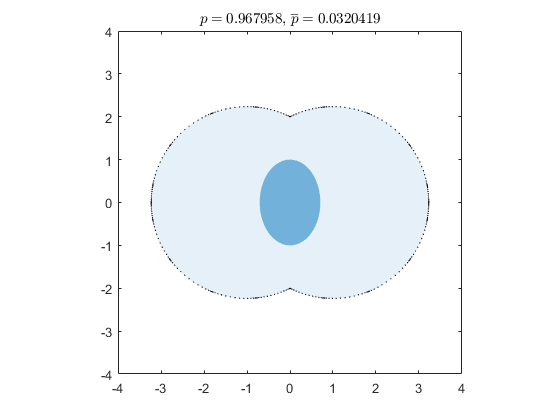

mu=[0;0]; v=[.5 0; 0 1];

circle_left=@(x,y) -(x+1).^2-y.^2+5;
circle_right=@(x,y) -(x-1).^2-y.^2+5;

circle_union=@(x,y) max(circle_left(x,y), circle_right(x,y));
integrate_normal(mu,v,circle_union,'dom_type','fun','fun_span',5);
axis image; xlim([-4 4]); ylim([-4 4])

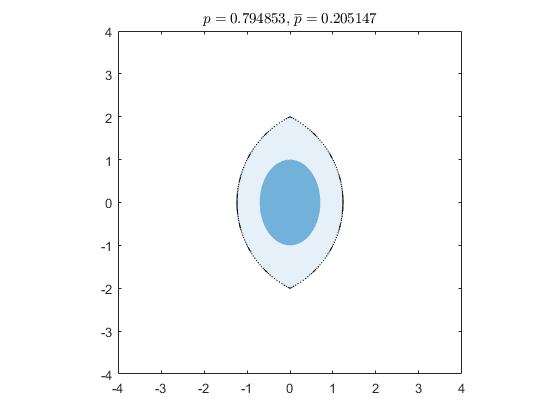


circle_intersection=@(x,y) min(circle_left(x,y), circle_right(x,y));
figure
integrate_normal(mu,v,circle_intersection,'dom_type','fun','fun_span',5);
axis image; xlim([-4 4]); ylim([-4 4])

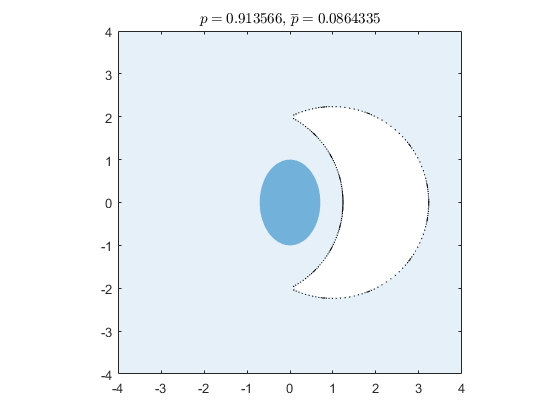


crescent=@(x,y) max(circle_left(x,y), -circle_right(x,y));
figure
integrate_normal(mu,v,crescent,'dom_type','fun','fun_span',5);
axis image; xlim([-4 4]); ylim([-4 4])

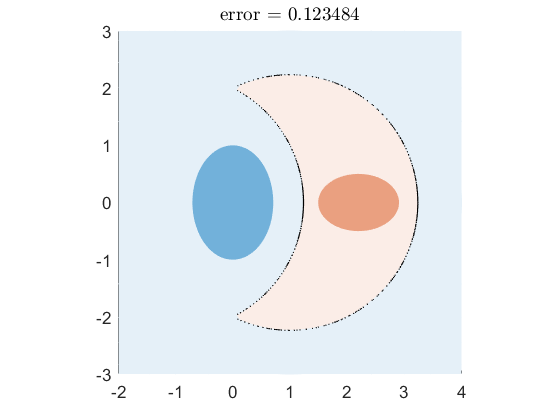


% classify normals using this domain
mu_2=[2.2;0];
v_2=[.5 0; 0 .25];
classify_normals([mu,v],[mu_2,v_2],'dom',crescent,'dom_type','fun','fun_span',5);
axis image; xlim([-2 4]); ylim([-3 3])
set(gca,'fontsize',13); box off

## Classify in 3d

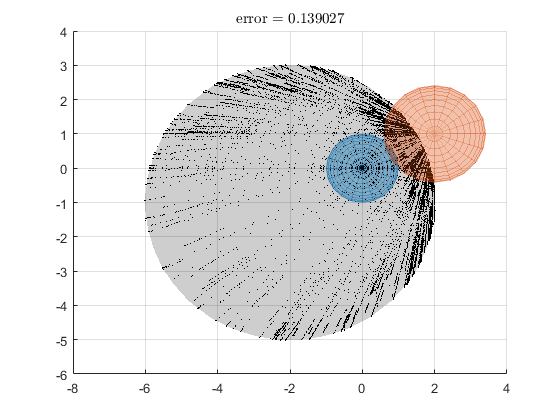

results = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [3×11936 double]
         norm_errmat: [2×2 double]
            norm_err: 0.1390
         norm_dprime: 2.1694
    norm_maha_dprime: 2


mu_1=[0;0;0]; v_1=eye(3);
mu_2=[2;1;1]; v_2=2*eye(3);

results=classify_normals([mu_1,v_1],[mu_2,v_2])

## Estimate tiny errors (large $d'$) with high accuracy

format long
dprime_true=75

dprime_true =     75



mu_1=[0;0;0]; v=eye(3);
mu_2=dprime_true*[1;0;0];

results=classify_normals([mu_1,v],[mu_2,v],'AbsTol',0,'RelTol',1e-2)

results = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [3×14112 double]
         norm_errmat: [2×2 double]
            norm_err: 4.608155172364448e-308
         norm_dprime: 74.999967581801229
    norm_maha_dprime: 75


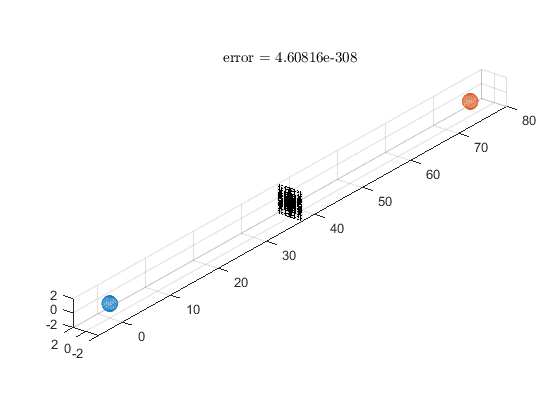

axis image; xlim([-5 80]); ylim([-2 2]); zlim([-2 2]); view(-53,25)

dprime_computed=results.norm_dprime

dprime_computed =   74.999967581801229


format

## PAPER accuracy vs separation between the normals

mu_1=[0;0;0];

% both normals have the same covariance, so we can check against
% the true d' (Mahalanobis distance).
v=[1 .5 .7;
  .5  2  1 ;
  .7  1  3];

steps=linspace(1,100,10);
d_true=nan(size(steps));
d_gx2=nan(size(steps));
d_ray=nan(size(steps));

parfor i=1:length(steps)
    i
    mu_2=steps(i)*[1;1;1];
    
    results_gx2=classify_normals([mu_1,v],[mu_2,v],'method','gx2','AbsTol',0,'RelTol',0,'plotmode',false);
    d_true(i)=results_gx2.norm_maha_dprime;
    d_gx2(i)=results_gx2.norm_dprime;
    
    results_ray=classify_normals([mu_1,v],[mu_2,v],'method','ray','AbsTol',0,'RelTol',0,'plotmode',false);
    d_ray(i)=results_ray.norm_dprime;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans =

     1


ans =

     2


ans =

     3


ans =

     4

> In integral2Calc>integral2t/tensor (line 247)
In integral2Calc>integral2t (line 55)
In integral2Calc (line 9)
In integral2 (line 106)
In int_norm_ray (line 46)
In integrate_normal (line 48)
In classify_normals (line 186)
In parallel_function>make_general_channel/channel_general (line 832)
In remoteParallelFunction (line 67)
> In integral2Calc>integral2t/tensor (line 2

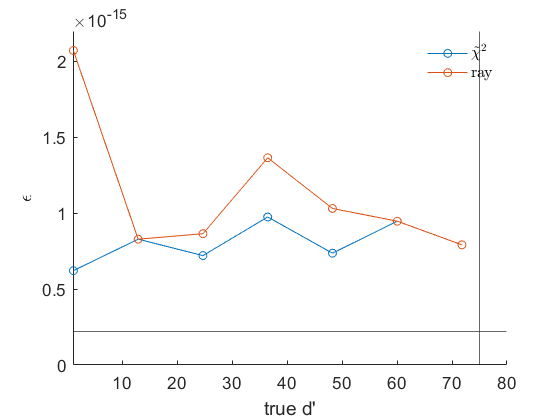


rel_err_gx2=abs(d_gx2-d_true)./d_true;
rel_err_ray=abs(d_ray-d_true)./d_true;

figure; hold on
plot(d_true,rel_err_gx2,'-o')
plot(d_true,rel_err_ray,'-o')
xline(-2*norminv(realmin)) % largest computable d', corr. to the smallest possible error representable in double-precision 
yline(eps) % machine epsilon for double precision
xlim([1 80]); ylim([0 2.2e-15])
xlabel 'true d'''
ylabel('$\epsilon$','interpreter','latex')
legend({'$\tilde{\chi}^2$','ray'},'interpreter','latex');
set(gca,'fontsize',13); box off; legend boxoff

## PAPER Integrate in a torus defined by implicit function $f(x)>0$

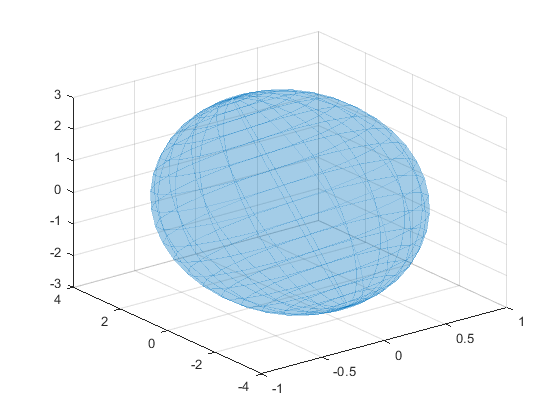

mu=[0;0;0];
v=[1 0 0;
   0 8 4;
   0 4 8];

% plot the error ellipsoid of the normal
figure; plot_normal(mu,v);

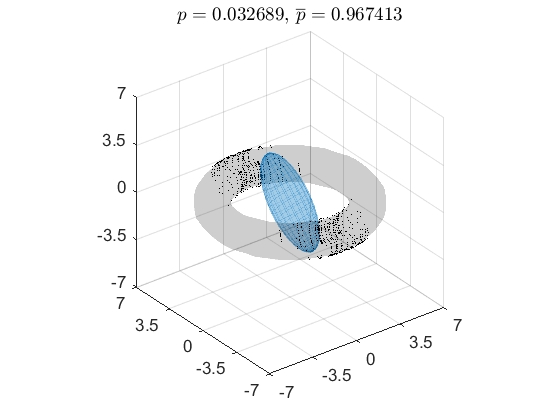


fun_torus=@(x1,x2,x3) 1.5-(5-(x1.^2+x2.^2).^0.5).^2-x3.^2;
figure;
integrate_normal(mu,v,fun_torus,'dom_type','fun','fun_span',3,'fun_resol',10,'RelTol',1e-1);
axis image; xlim([-7 7]); ylim([-7 7]); zlim([-7 7]);
set(gca,'xtick',linspace(-7,7,5)); set(gca,'ytick',linspace(-7,7,5)); set(gca,'ztick',linspace(-7,7,5))
set(gca,'fontsize',13)

### Plot the pdf and cdf of $f(x)$

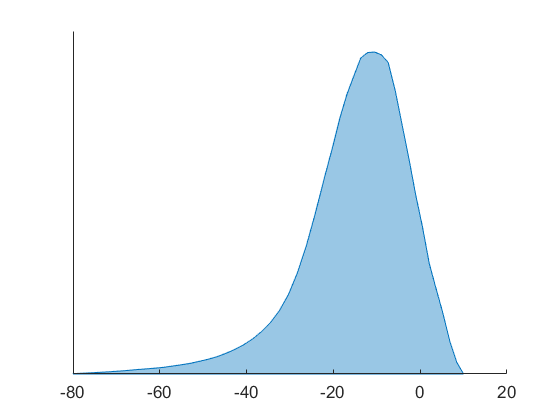

x=[linspace(-80,-20,30) linspace(-20,10,20)];
pdf=norm_fun_pdf(x,mu,v,fun_torus,'fun_span',3,'fun_resol',10,'RelTol',1e-1,'dx',8);
colors=colororder;
figure; area(x,pdf,'facecolor',colors(1,:),'facealpha',0.4,'edgecolor',colors(1,:))
set(gca,'ytick',[]); set(gca,'fontsize',13); box off

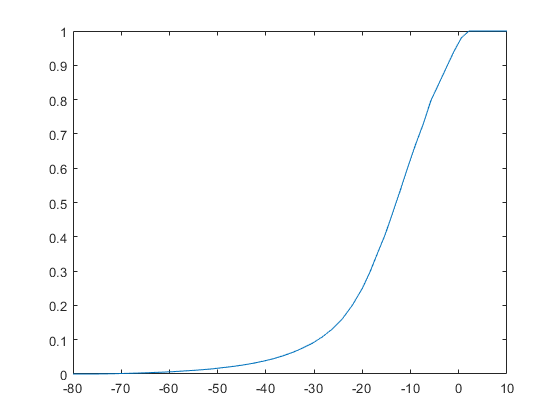

cdf=norm_fun_cdf(x,mu,v,fun_torus,'fun_span',3,'fun_resol',10,'RelTol',1e-1);
figure; plot(x,cdf)

## PAPER Integrate in 4d

Integrate outside the sphere of radius 5, i.e. $x1^2+x2^2+x3^2+x4^2>5^2$, i.e. `x'*eye(4)*x + zeros(4,1)'*x -25 >0`

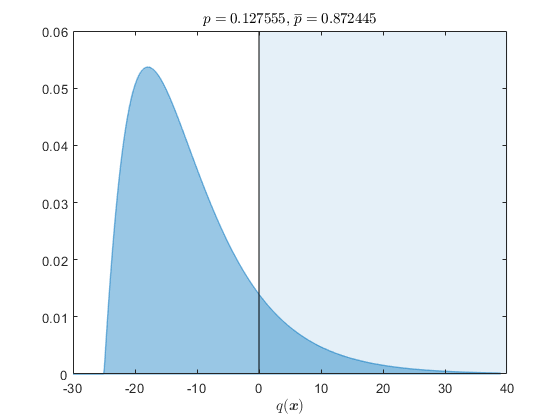

mu=[1;1;1;1]; v=diag([1 2 3 4]);

dom_quad.q2=eye(4);
dom_quad.q1=zeros(4,1);
dom_quad.q0=-25;

p=integrate_normal(mu,v,dom_quad); xlim([-30 40]); ylim([0 .06]);

## PAPER Classify in 4d, with priors and outcome values

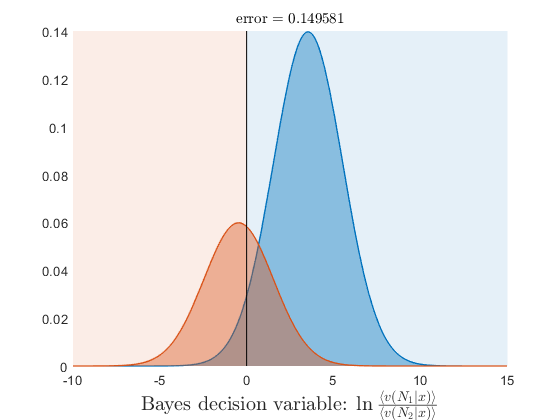

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1496
    norm_valmat: [2×2 double]
       norm_val: 1.5236


mu_1=[0;0;0;0]; v_1=eye(4);
mu_2=[1;1;1;1]; v_2=eye(4);

% here the Bayes decision variable is normally distributed
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[2 0; 0 1])

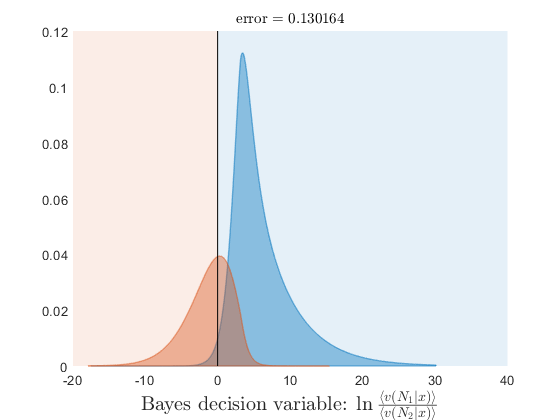

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1302
    norm_valmat: [2×2 double]
       norm_val: 2.9431



mu_1=[0;0;0;0];
v_1=[1 0 0 0;
     0 2 -1 0;
     0 -1 3 2;
     0 0 2 4];

mu_2=1.5*[1;1;1;1];
v_2=[2 0 0 0;
     0 2 0 0;
     0 0 2 0;
     0 0 0 1];

% correct classification of class 1 is valued 4x than class 2
% here the Bayes decision variable is distributed as a generalized chi-square
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[4 0; 0 1])

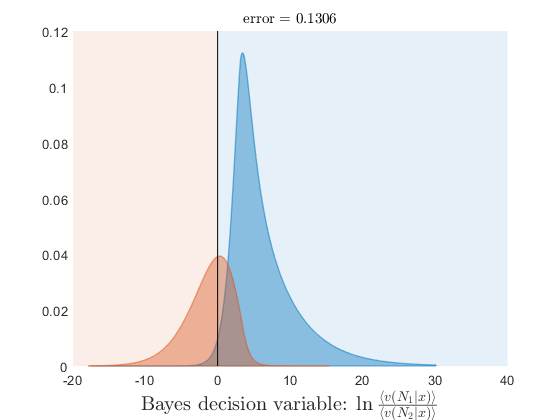

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_bd_pts: [4×2494 double]
    norm_errmat: [2×2 double]
       norm_err: 0.1306
    norm_valmat: [2×2 double]
       norm_val: 2.9372


% use ray method (with Monte Carlo integration)
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[4 0; 0 1],'method','ray','mc_samples',1e3)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -4587         
     1           16            -4599         initial simplex
     2           18            -4616         expand
     3           19            -4616         reflect
     4           20            -4616         reflect
     5           21            -4616         reflect
     6           22            -4616         reflect
     7           23            -4616         reflect
     8           24            -4616         reflect
     9           25            -4616         reflect
    10           26            -4616         reflect
    11           27            -4616         reflect
    12           28            -4616         reflect
    13           29            -4616         reflect
    14           30            -4616         reflect
    15           31            -4616         reflect
    16           32            -4616         reflect
    17           33            -4616      

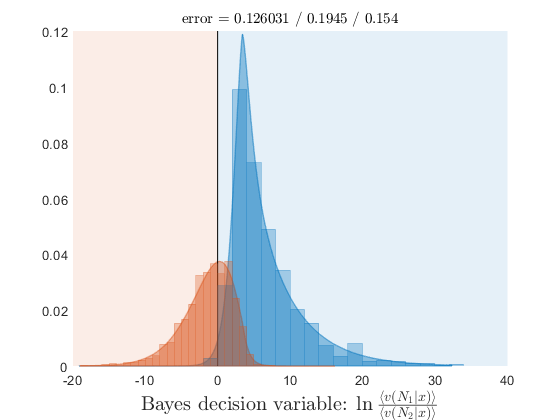

results = struct with fields:
            norm_bd: [1×1 struct]
        norm_errmat: [2×2 double]
           norm_err: 0.1260
        norm_valmat: [2×2 double]
           norm_val: 2.9483
        samp_errmat: [2×2 double]
           samp_err: 0.1945
        samp_valmat: [2×2 double]
           samp_val: 4587
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.1540
    samp_opt_valmat: [2×2 double]
       samp_opt_val: 4623



% now classify using samples
n_samp=1e3;
results=classify_normals(mvnrnd(mu_1',v_1,n_samp),mvnrnd(mu_2',v_2,n_samp),'input_type','samp','prior_1',.7,'vals',[4 0; 0 1])

## PAPER Integrate in a 4d polyhedron, using Monte Carlo

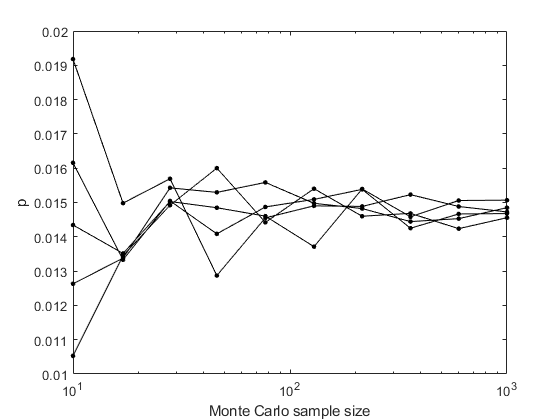

mu=zeros(4,1); v=eye(4);

fun=@(x1,x2,x3,x4) 1-abs(x1)-abs(x2)-abs(x3)-abs(x4);
mc_samples=round(10.^linspace(1,3,10)); % # of Monte Carlo samples
n_repeat=5;
plist=nan(length(mc_samples),n_repeat);

for k=1:n_repeat
    for i=1:length(mc_samples)
        p=integrate_normal(mu,v,fun,'dom_type','fun','fun_span',3,'fun_resol',10,'mc_samples',mc_samples(i),'plotmode',false);
        plist(i,k)=p;
    end
end

plot(mc_samples,plist,'-k','marker','.','markersize',10)
xlabel 'Monte Carlo sample size'
ylabel 'p'
set(gca,'xscale','log')

## PAPER Integrate vector-valued function of a normal

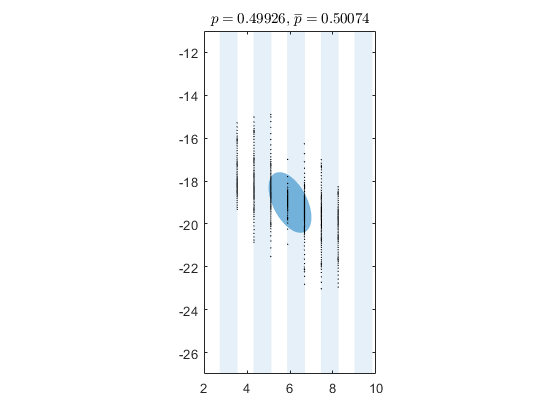

% (x,y) is a normal vector with these parameters:
mu=[6;-19];
v=[1 -.7; -.7 2];

% functions of the normal vector
f1=@(x,y) cos(4*x);
f2=@(x,y) cos(4*y);

% integrate f1 above 0
figure;
integrate_normal(mu,v,f1,'dom_type','fun','fun_span',3);
axis image; xlim([2 10]); ylim([-27 -11]);

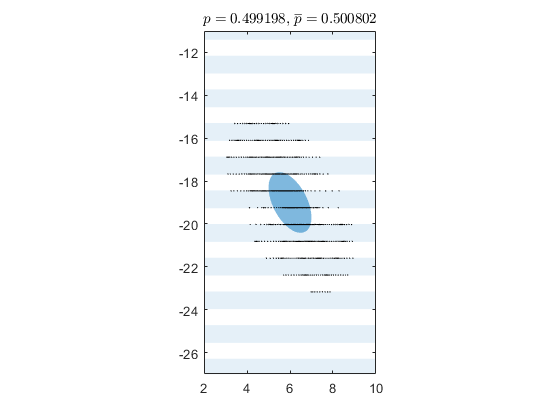


% integrate f2 above 0
figure;
integrate_normal(mu,v,f2,'dom_type','fun','fun_span',3);
axis image; xlim([2 10]); ylim([-27 -11]);

Probability that $cos(5x)$ and $cos(5y)$ are both > 0, i.e. integrate vector function `f=[f1,f2]` in the domain `f1>0` and `f2>0`, i.e. `min(f1,f2)>0`.

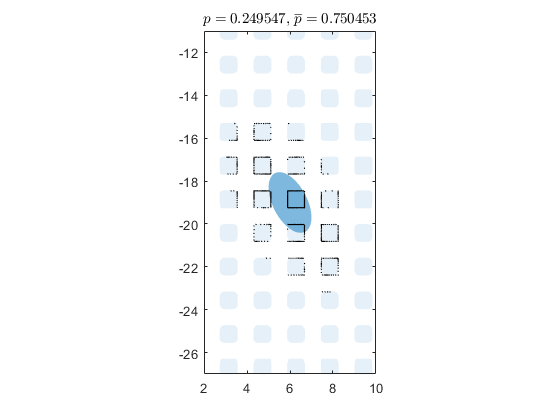

f_domain1=@(x,y) min(f1(x,y),f2(x,y));

figure;
integrate_normal(mu,v,f_domain1,'dom_type','fun','fun_span',3);
axis image; xlim([2 10]); ylim([-27 -11]);

Probability that $cos(5x) + cos(5y) > 0.5$, i.e. integrate the vector function in the implicit domain `f1+f2-0.5>0`.

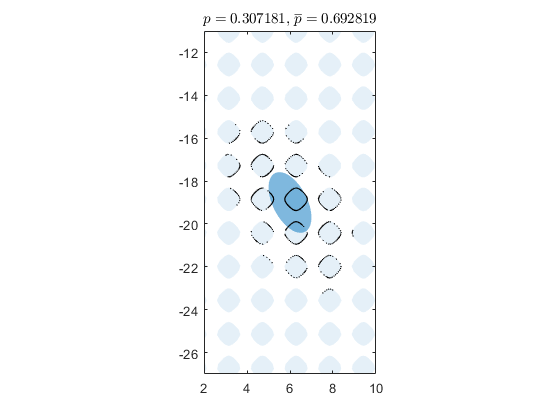

f_domain2=@(x,y) f1(x,y)+f2(x,y)-.5;

figure;
integrate_normal(mu,v,f_domain2,'dom_type','fun','fun_span',3);
axis image; xlim([2 10]); ylim([-27 -11]);

## Classifying 3 1d normals

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3


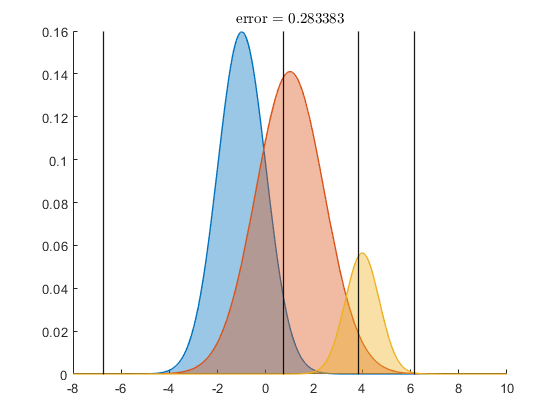

results = struct with fields:
    norm_bd_pts: {3×1 cell}
    norm_errmat: [3×3 double]
       norm_err: 0.2834
    norm_valmat: [3×3 double]
       norm_val: 1.8466


normals=struct;
normals(1).mu=-1; normals(1).v=1;
normals(2).mu=1; normals(2).v=2;
normals(3).mu=4; normals(3).v=.5;

% priors and outcome values
priors=[.4 .5 .1];
vals=[4 0 0; 0 1 -2; 0 0 1];

results=classify_normals_multi(normals,'priors',priors,'vals',vals)

## Classifying 4 2d normals

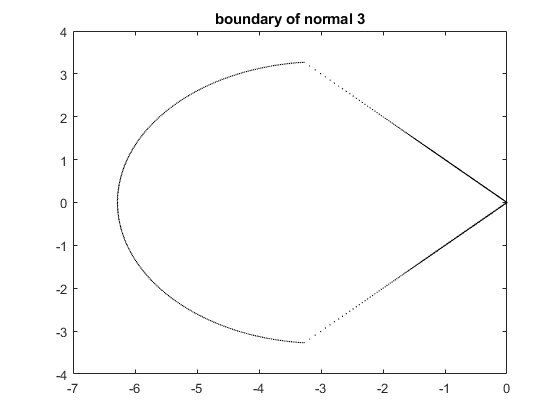

% define struct of all normals
normals=struct;
normals(1).mu=[1;0]; normals(1).v=2*eye(2);
normals(2).mu=[0;1]; normals(2).v=eye(2);
normals(3).mu=[-1;0]; normals(3).v=eye(2);
normals(4).mu=[0;-1]; normals(4).v=eye(2);

% plot the multi-class boundary of normal 3
plot_boundary(@(n,mu,v) opt_class_multi(n,normals,3,'mu',mu,'v',v),2,'mu',normals(3).mu,'dom_type','ray_scan')
title 'boundary of normal 3'

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


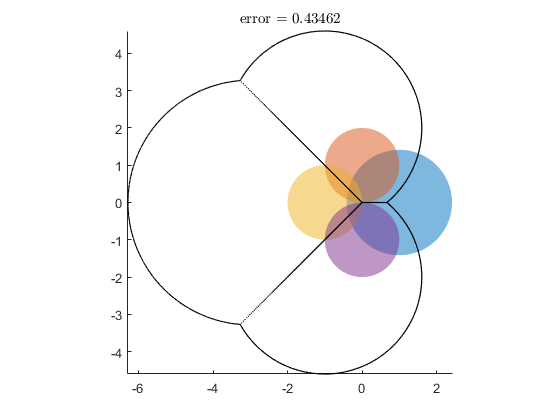


% classify
results=classify_normals_multi(normals); axis image


% now classify using samples from these normals, with outcome values
samples=struct;
for i=1:4
    samples(i).sample=mvnrnd(normals(i).mu,normals(i).v,1e4);
end
vals=diag([1 2 3 4]);
results_samp=classify_normals_multi(samples,'input_type','samp','vals',vals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.4578
    norm_valmat: [4×4 double]
       norm_val: 1.5608
    samp_errmat: [4×4 double]
       samp_err: 0.4552
    samp_valmat: [4×4 double]
       samp_val: 62804


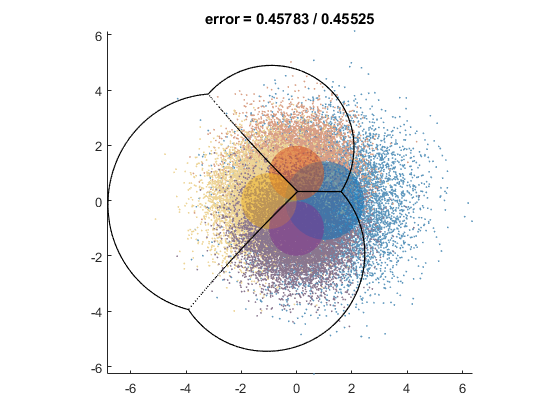

axis image


% now classify using samples from t distributions similar to these normals
samples=struct;
for i=1:4
    samples(i).sample=mvtrnd(normals(i).v,3,1e4)+normals(i).mu';
end
results_samp=classify_normals_multi(samples,'input_type','samp')

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.5578
    samp_errmat: [4×4 double]
       samp_err: 0.4583


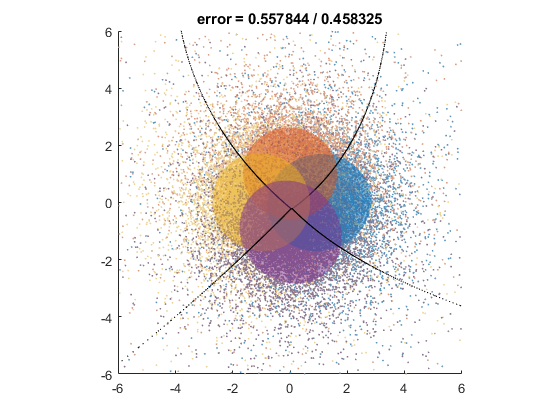

axis image; xlim([-6 6]); ylim([-6 6]);

## PAPER Classifying 7 2d normals

% define struct of all normals
normals=struct;
normals(1).mu=[2;0]; normals(1).v=[2 1; 1 2];
normals(2).mu=[0;1]; normals(2).v=[.5 0; 0 1];
normals(3).mu=[-1;0]; normals(3).v=[1 .3; .3 1];
normals(4).mu=[0;-1]; normals(4).v=[.5 -.5; -.5 1];
normals(5).mu=[-2;2]; normals(5).v=.5*[1 1; 1 5];
normals(6).mu=[2;-3]; normals(6).v=.3*eye(2);
normals(7).mu=[-2;-2.5]; normals(7).v=[1 0; 0 .1];

% classify
results=classify_normals_multi(normals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 1 in domain 5
Integrating normal 1 in domain 6
Integrating normal 1 in domain 7
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 2 in domain 5
Integrating normal 2 in domain 6
Integrating normal 2 in domain 7
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 3 in domain 5
Integrating normal 3 in domain 6
Integrating normal 3 in domain 7
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4
Integrating normal 4 in domain 5
Integrating normal 4 in domain 6
Integrating normal 4 in domain 7
Integrating normal 5 in domain 1
Integrating normal 5 in domain 2
Integratin

results = struct with fields:
    norm_bd_pts: {7×1 cell}
    norm_errmat: [7×7 double]
       norm_err: 0.2319


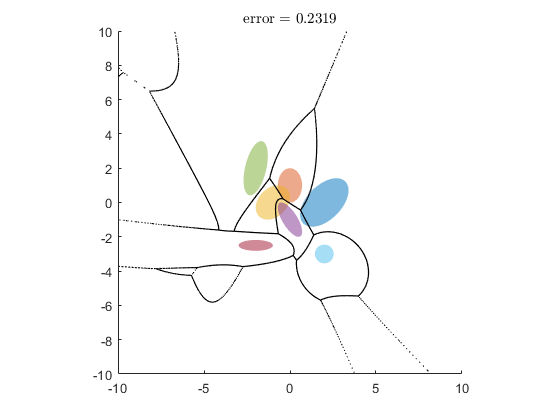

axis image; xlim([-10 10]); ylim([-10 10]);

## Classifying 4 3d normals

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


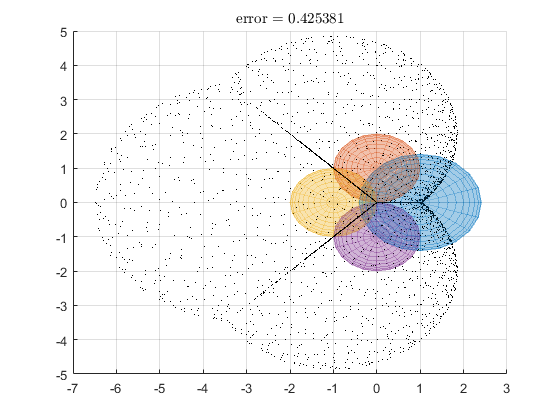

results = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.4254


normals=struct;
normals(1).mu=[1;0;0]; normals(1).v=2*eye(3);
normals(2).mu=[0;1;0]; normals(2).v=eye(3);
normals(3).mu=[-1;0;0]; normals(3).v=eye(3);
normals(4).mu=[0;-1;0]; normals(4).v=eye(3);

results=classify_normals_multi(normals)

## PAPER Classifying 4 4d $t$ distribution samples

Integrating normal 1 in domain 1


Integrating normal 1 in domain 2


Integrating normal 1 in domain 3


Integrating normal 1 in domain 4


Integrating normal 2 in domain 1


Integrating normal 2 in domain 2


Integrating normal 2 in domain 3


Integrating normal 2 in domain 4


Integrating normal 3 in domain 1


Integrating normal 3 in domain 2


Integrating normal 3 in domain 3


Integrating normal 3 in domain 4


Integrating normal 4 in domain 1


Integrating normal 4 in domain 2


Integrating normal 4 in domain 3


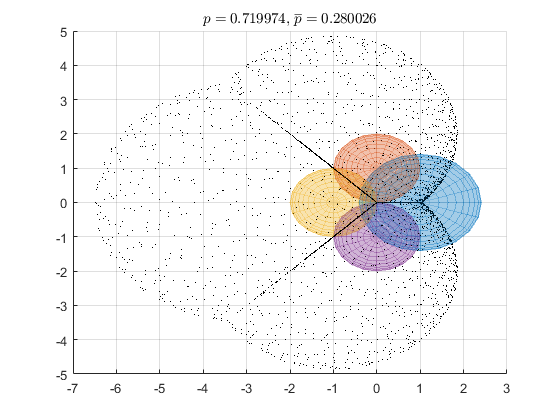

Integrating normal 4 in domain 4


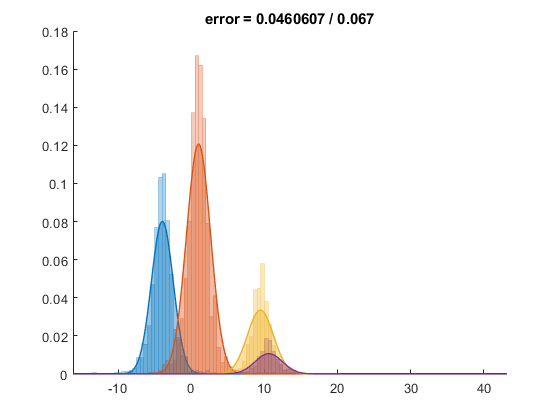

results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.0461
    samp_errmat: [4×4 double]
       samp_err: 0.0670


params=struct;
params(1).mu=[0;-4;-2;-2]; params(1).v=diag([1 2 3 4]);
params(2).mu=[1;1;0;0]; params(2).v=eye(4)/4;
params(3).mu=[3;4;5;7]; params(3).v=eye(4);
params(4).mu=[5;5;7;4]; params(4).v=eye(4);

priors=[.3 .5 .15 .05];

n_samp=1e3;
samples=struct;
for i=1:4
    samples(i).sample=mvtrnd(params(i).v,3,n_samp)+params(i).mu';
end
results_samp=classify_normals_multi(samples,'input_type','samp','priors',priors,'mc_samples',1e3,'plotmode',[1;1;1;1])

## PAPER testing the normal approximation for 2 2d classes

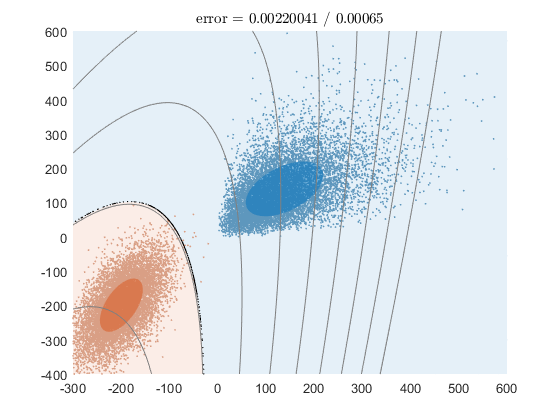

N_samp=1e4; n_samp=1e2;

mu_1=[5 5]; v_1=[1 .5; .5 1]; samp_1=mvnrnd(mu_1,v_1,N_samp).^3; % not normal
mu_2=[-200 -200]; v_2=[1 1; 1 3]*2e3; samp_2=mvnrnd(mu_2,v_2,N_samp);

results=classify_normals(samp_1,samp_2,'input_type','samp','samp_opt',false);
xlim([-300 600]); ylim([-400 600]); hold on
bd=results.norm_bd;

q0s=linspace(-100,35,100)';
true_p11=nan(size(q0s)); true_p2_2=nan(size(q0s)); % p(1|1)
norm_p11=nan(size(q0s)); norm_p2_2=nan(size(q0s));

for i=1:length(q0s)
    bd_shift=bd; bd_shift.q0=q0s(i);
    if ~rem(i,10)
        plot_boundary(bd_shift,2,'plot_type','line','line_color',.5*[1 1 1]);
    end
    results_shift=classify_normals(samp_1,samp_2,'input_type','samp','dom',bd_shift,'samp_opt',false,'plotmode',false);
    
    % true outcomes
    true_p11(i)=results_shift.samp_errmat(1,1)/N_samp;
    true_p2_2(i)=results_shift.samp_errmat(2,2)/N_samp;
    
    % normal outcomes
    norm_p11(i)=results_shift.norm_errmat(1,1)/.5;
    norm_p2_2(i)=results_shift.norm_errmat(2,2)/.5;
    
end

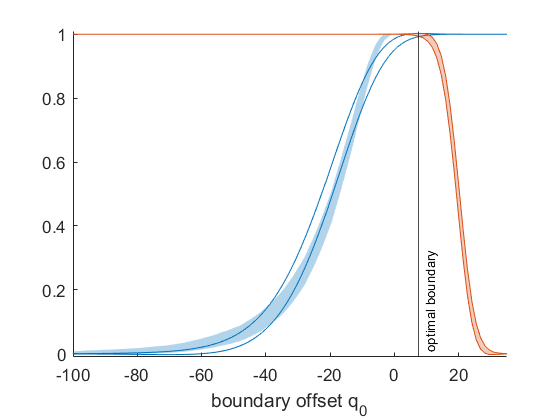

true_p1_1_sd=sqrt(true_p11.*(1-true_p11)/n_samp);
true_p2_2_sd=sqrt(true_p2_2.*(1-true_p2_2)/n_samp);

norm_p1_1_sd=sqrt(norm_p11.*(1-norm_p11)/n_samp);
norm_p2_2_sd=sqrt(norm_p2_2.*(1-norm_p2_2)/n_samp);

figure; hold on
colors=colororder;
xline(bd.q0,'k','optimal boundary','LabelVerticalAlignment','bottom') % optimal criterion

% p(1|1)
x=q0s; y=true_p11; dy=true_p1_1_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],colors(1,:),'facealpha',.3,'linestyle','none');

y=norm_p11; dy=norm_p1_1_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',colors(1,:));

% p(2|2)
y=true_p2_2; dy=true_p2_2_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],colors(2,:),'facealpha',.3,'linestyle','none');

y=norm_p2_2; dy=norm_p2_2_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',colors(2,:));

xlim([min(q0s) max(q0s)]); ylim([-.01 1.01]); xlabel('boundary offset q_0')
set(gca,'fontsize',13); box off

## PAPER testing the normal approximation for 4 4d $t$ distributions

n_class=4; N_samp=1e4; n_samp=1e2;

% t distribution parameters
params_t=struct;
params_t(1).mu=[0;-4;-2;-2]; params_t(1).v=diag([1 2 3 4]);
params_t(2).mu=[1;1;0;0]; params_t(2).v=eye(4)/4;
params_t(3).mu=[3;4;5;7]; params_t(3).v=eye(4);
params_t(4).mu=[5;5;7;4]; params_t(4).v=eye(4);

samples=struct; params_samp=struct;
for i=1:4
    % generate t samples
    sample=mvtrnd(params_t(i).v,3,N_samp)+params_t(i).mu';
    samples(i).sample=sample;
    % mean and covariance of samples
    params_samp(i).mu=mean(sample)';
    params_samp(i).v=cov(sample)';
end

len_fam=10;
prior_fam=10.^linspace(-6,12,len_fam)';
vscale_fam=10.^linspace(-1,3,len_fam)';

true_p22_mean=nan(len_fam,1);
true_pe_mean=nan(len_fam,1);
true_pe_sd=nan(len_fam,1);

norm_p22_mean=nan(len_fam,1);
norm_pe_mean=nan(len_fam,1);
norm_pe_sd=nan(len_fam,1);

parfor i=1:len_fam
    i
    % generate family of classification domains
    
    % uncomment when varying prior, comment when varying variance
    priors_shift=[1 prior_fam(i) 1 1]; priors_shift=priors_shift/sum(priors_shift);
    domains_shift=cell(n_class,1);
    for k=1:n_class
        domains_shift{k}=@(n,mu,v) opt_class_multi(n,params_samp,k,'mu',mu,'v',v,'priors',priors_shift);
    end
    
    % uncomment when varying variance, comment when varying prior
%     params_samp_shift=params_samp;
%     for k=1:n_class
%         params_samp_shift(k).v=vscale_fam(i)*params_samp(k).v;
%     end    
%     domains_shift=cell(n_class,1);
%     for k=1:n_class
%         domains_shift{k}=@(n,mu,v) opt_class_multi(n,params_samp_shift,k,'mu',mu,'v',v);
%     end
    
    results_shift=classify_normals_multi(samples,'input_type','samp','doms',domains_shift,'mc_samples',5e3,'plotmode',false);
    
    % true error rates
    true_p22_mean(i)=results_shift.samp_errmat(2,2)/N_samp;
    true_pe_mean(i)=results_shift.samp_err;
    samp_errmat_p=results_shift.samp_errmat/(n_class*N_samp);
    errs=sum(~eye(length(samples)).*samp_errmat_p,2);
    accs=diag(samp_errmat_p);
    true_pe_sd(i)=sqrt(sum(errs.*accs)/n_samp);
    
    % normal error rates
    norm_p22_mean(i)=results_shift.norm_errmat(2,2)/sum(results_shift.norm_errmat(2,:));
    norm_pe_mean(i)=results_shift.norm_err;
    errs=sum(~eye(length(samples)).*results_shift.norm_errmat,2);
    accs=diag(results_shift.norm_errmat);
    norm_pe_sd(i)=sqrt(sum(errs.*accs)/n_samp);
    
end


ans =

     1


ans =

     2


ans =

     3


ans =

     4

Integrating normal 1 in domain 1
Integrating normal 1 in domain 1
Integrating normal 1 in domain 1
Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 2
Integrating normal 1 in domain 2
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 3
Integrating normal 1 in domain 3
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 1 in domain 4
Integrating normal 1 in domain 4
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 1
Integrating normal 2 in domain 1
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 2
Integrating normal 2 in domain 2
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 3
Integrating normal 2 in domain 3
Integrating normal 2 in domain 3
Integrating 

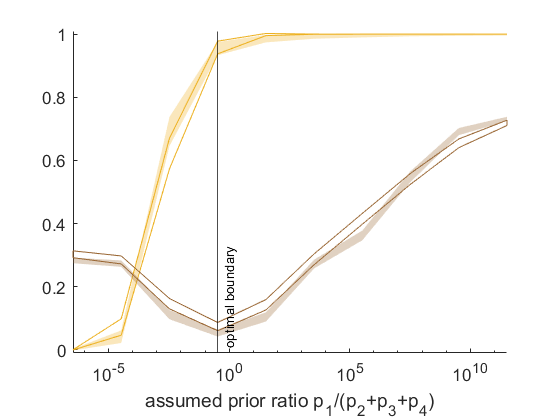

true_p22_sd=sqrt(true_p22_mean.*(1-true_p22_mean)/n_samp);
norm_p22_sd=sqrt(norm_p22_mean.*(1-norm_p22_mean)/n_samp);

figure; hold on;

% uncomment when varying prior, comment when varying variance
xline(1/3,'k','optimal boundary','LabelVerticalAlignment','bottom')
xlabel('assumed prior ratio p_1/(p_2+p_3+p_4)')
x=prior_fam/3;

% uncomment when varying variance, comment when varying prior
% xline(1,'k','optimal boundary','LabelVerticalAlignment','bottom')
% xlabel('assumed variance scale')
% x=vscale_fam;

% p(2|2)
y=true_p22_mean; dy=true_p22_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],[0.9290 0.6940 0.1250],'facealpha',.3,'linestyle','none');

y=norm_p22_mean; dy=norm_p22_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',[0.9290 0.6940 0.1250]);

% pe
y=true_pe_mean; dy=true_pe_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],[0.6 0.4 0.2],'facealpha',.3,'linestyle','none');

y=norm_pe_mean; dy=norm_pe_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',[0.6 0.4 0.2]);

xlim([min(x) max(x)]); set(gca,'xscale','log'); ylim([-.01 1.01])
set(gca,'fontsize',13); box off

## PAPER Actual vision research data: detecting targets on natural scenes

absent=importdata('target_absent.txt',',',1);
present=importdata('target_present.txt',',',1);

results=classify_normals(absent.data,present.data,'input_type','samp')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -4569         
     1           11            -4579         initial simplex
     2           13            -4582         expand
     3           14            -4582         reflect
     4           15            -4582         reflect
     5           16            -4582         reflect
     6           17            -4582         reflect
     7           19            -4583         reflect
     8           20            -4583         reflect
     9           21            -4583         reflect
    10           23            -4585         reflect
    11           24            -4585         reflect
    12           25            -4585         reflect
    13           27            -4586         reflect
    14           28            -4586         reflect
    15           29            -4586         reflect
    16           41            -4586         shrink
    17           42            -4586       

results = struct with fields:
             norm_bd: [1×1 struct]
         norm_bd_pts: [3×3754 double]
         norm_errmat: [2×2 double]
            norm_err: 8.0400e-05
         norm_dprime: 7.5475
    norm_maha_dprime: 6.8175
         samp_errmat: [2×2 double]
            samp_err: 0.0067
         samp_dprime: 4.9418
             samp_dv: {[2300×1 double]  [2300×1 double]}
         samp_opt_bd: [1×1 struct]
         samp_opt_dv: {[2300×1 double]  [2300×1 double]}
     samp_opt_bd_pts: [3×26070 double]
     samp_opt_errmat: [2×2 double]
        samp_opt_err: 0.0026
     samp_opt_dprime: 5.5866


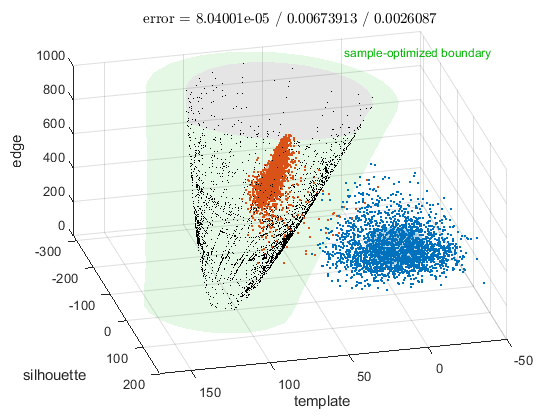


axis normal
xlim([-50 170]); ylim([-320 200]); zlim([0 1000]); view(166,40);
xlabel('template'); ylabel('silhouette'); zlabel('edge');

## PAPER Actual vision research data: detecting camouflage

load camouflage_edge_data
results_joint_2=classify_normals([edge_powers_2(:,1),edge_lpr_2(:,1)],[edge_powers_2(:,2),edge_lpr_2(:,2)],'input_type','samp');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1     -1.99656e+06         
     1            7     -1.99716e+06         initial simplex
     2            8     -1.99716e+06         reflect
     3           10     -1.99716e+06         contract inside
     4           12     -1.99716e+06         contract inside
     5           14     -1.99716e+06         contract outside
     6           16     -1.99716e+06         contract outside
     7           18     -1.99716e+06         contract inside
     8           20     -1.99716e+06         contract inside
     9           21     -1.99716e+06         reflect
    10           23     -1.99719e+06         contract inside
    11           25     -1.99756e+06         contract inside
    12           27     -1.99756e+06         contract inside
    13           29     -1.99758e+06         contract inside
    14           31     -1.99763e+06         contract inside
    15           33     -1.99774e+06         contract ins

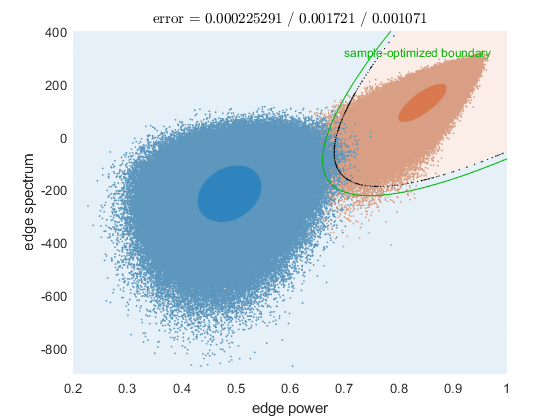

xlim([0.2 1]); ylim([-900 400])
xlabel 'edge power'; ylabel 'edge spectrum'

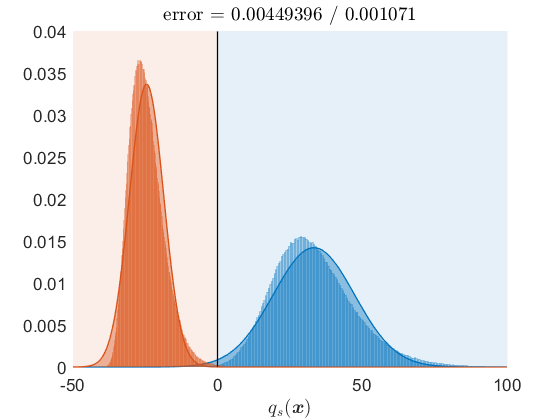


results_dv_2=classify_normals(results_joint_2.samp_opt_dv{1},results_joint_2.samp_opt_dv{2},'input_type','samp','dom',@(x) x,'dom_type','fun','samp_opt',false);
xlim([-50 100]); ylim([0 .04]);
set(gca,'fontsize',13); box off
xlabel('$q_s(${\boldmath$x$}$)$','interpreter','latex');


results_joint_4=classify_normals([edge_powers_4(:,1),edge_lpr_4(:,1)],[edge_powers_4(:,2),edge_lpr_4(:,2)],'input_type','samp','plotmode',false);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1      -1.9574e+06         
     1            7      -1.9574e+06         initial simplex
     2            9      -1.9574e+06         contract inside
     3           11      -1.9574e+06         contract outside
     4           13      -1.9574e+06         contract outside
     5           14      -1.9574e+06         reflect
     6           16      -1.9574e+06         contract inside
     7           18      -1.9574e+06         contract inside
     8           20      -1.9574e+06         contract outside
     9           22      -1.9574e+06         contract inside
    10           24      -1.9574e+06         contract inside
    11           26      -1.9574e+06         contract inside
    12           28     -1.95741e+06         contract inside
    13           30     -1.95782e+06         contract inside
    14           32     -1.95782e+06         contract outside
    15           34     -1.95783e+06         co

results_joint_8=classify_normals([edge_powers_8(:,1),edge_lpr_8(:,1)],[edge_powers_8(:,2),edge_lpr_8(:,2)],'input_type','samp','plotmode',false);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1     -1.78592e+06         
     1            7     -1.78592e+06         initial simplex
     2            9     -1.78592e+06         contract inside
     3           11     -1.78592e+06         contract inside
     4           13     -1.78592e+06         contract inside
     5           15     -1.78699e+06         contract outside
     6           17     -1.78713e+06         contract inside
     7           19     -1.78734e+06         contract outside
     8           21     -1.78746e+06         contract inside
     9           23     -1.78777e+06         contract inside
    10           25     -1.78777e+06         contract inside
    11           27      -1.7878e+06         contract inside
    12           29     -1.78788e+06         contract outside
    13           31     -1.78788e+06         contract outside
    14           33     -1.78792e+06         contract inside
    15           35     -1.78837e+06   


results_dv_joint=classify_normals([results_joint_2.samp_opt_dv{1},results_joint_4.samp_opt_dv{1},results_joint_8.samp_opt_dv{1}],[results_joint_2.samp_opt_dv{2},results_joint_4.samp_opt_dv{2},results_joint_8.samp_opt_dv{2}],'input_type','samp');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1     -1.99145e+06         
     1           11      -1.9929e+06         initial simplex
     2           12      -1.9929e+06         reflect
     3           13      -1.9929e+06         reflect
     4           14      -1.9929e+06         reflect
     5           15      -1.9929e+06         reflect
     6           16      -1.9929e+06         reflect
     7           17      -1.9929e+06         reflect
     8           19     -1.99367e+06         expand
     9           20     -1.99367e+06         reflect
    10           22     -1.99445e+06         expand
    11           23     -1.99445e+06         reflect
    12           24     -1.99445e+06         reflect
    13           25     -1.99445e+06         reflect
    14           26     -1.99445e+06         reflect
    15           27     -1.99445e+06         reflect
    16           29     -1.99523e+06         expand
    17           30     -1.99523e+06        

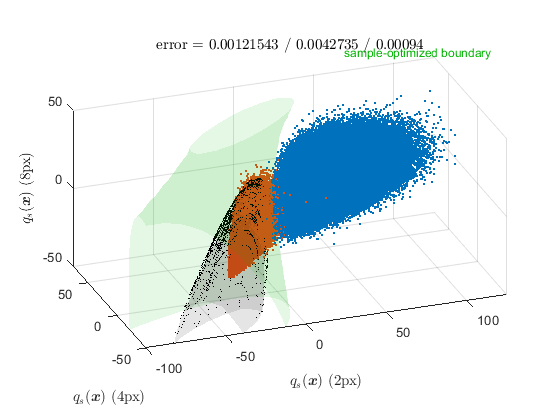

axis image; xlim([-100 125]); ylim([-50 75]); zlim([-50 50]); view(-20,24)
xlabel('$q_s(${\boldmath$x$}$)$ (2px)','interpreter','latex');
ylabel('$q_s(${\boldmath$x$}$)$ (4px)','interpreter','latex');
zlabel('$q_s(${\boldmath$x$}$)$ (8px)','interpreter','latex');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1     -1.99471e+06         
     1           29     -1.99689e+06         initial simplex
     2           30     -1.99689e+06         reflect
     3           31     -1.99689e+06         reflect
     4           32     -1.99689e+06         reflect
     5           34     -1.99689e+06         contract inside
     6           36     -1.99689e+06         contract inside
     7           38     -1.99689e+06         contract inside
     8           40     -1.99689e+06         contract inside
     9           41     -1.99689e+06         reflect
    10           43     -1.99689e+06         contract inside
    11           45     -1.99689e+06         contract inside
    12           46     -1.99689e+06         reflect
    13           48     -1.99689e+06         contract inside
    14           50     -1.99689e+06         contract inside
    15           52     -1.99689e+06         contract inside
    16           54   

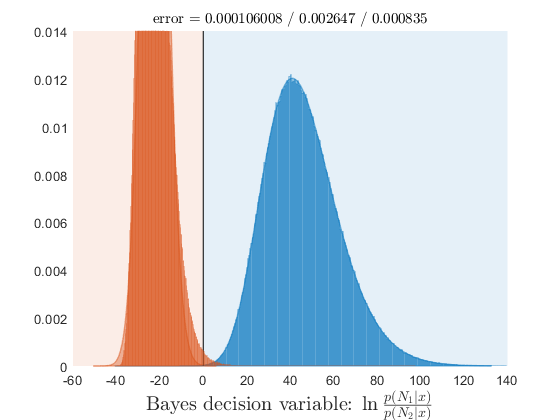


results_all=classify_normals([edge_powers_2(:,1),edge_lpr_2(:,1),...
                              edge_powers_4(:,1),edge_lpr_4(:,1),...
                              edge_powers_8(:,1),edge_lpr_8(:,1)],...
                             [edge_powers_2(:,2),edge_lpr_2(:,2),...
                              edge_powers_4(:,2),edge_lpr_4(:,2),...
                              edge_powers_8(:,2),edge_lpr_8(:,2)],'input_type','samp');

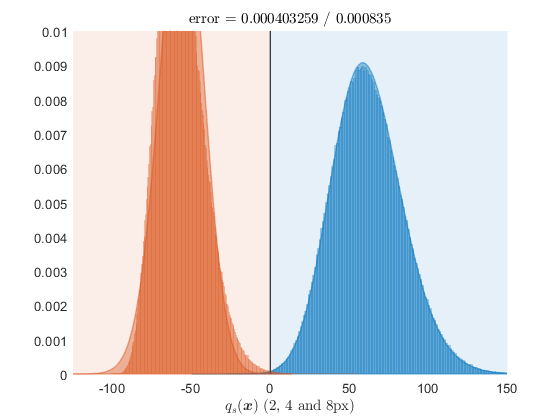

                          
results_all_samp_opt=classify_normals([edge_powers_2(:,1),edge_lpr_2(:,1),...
                              edge_powers_4(:,1),edge_lpr_4(:,1),...
                              edge_powers_8(:,1),edge_lpr_8(:,1)],...
                             [edge_powers_2(:,2),edge_lpr_2(:,2),...
                              edge_powers_4(:,2),edge_lpr_4(:,2),...
                              edge_powers_8(:,2),edge_lpr_8(:,2)],'input_type','samp',...
                              'dom',results_all.samp_opt_bd,'samp_opt',false);
xlabel('$q_s(${\boldmath$x$}$)$ (2, 4 and 8px)','interpreter','latex');
xlim([-125 150]);